clc; close all;
k = 4;
d = 30;
n = 5;
m = 1e5;

hmm_options.epsilon = 1/10;
hmm_options.method = "random";
hmm_options.distribution = 'Normal';

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-14;
cpd_options.th_relerr = 1e-7;
cpd_options.epsilon = 1/10;

alpha = 0.05;
rho = 0.85;

Nruns = 100;
ps = 1;

CoupledCost = zeros(2, Nruns);
CoupledTime = zeros(ps, Nruns);

T_hats = cell(n,1);
O_hats = cell(n,1);

P3 = cell(n,1);


[T, Os, pi, ~, ~] = generateHMM(k, d, n, hmm_options);
[seq, ~] = generate_multivariate_hmm_sequence(T, Os, pi, m);

[~, mins, maxs] = NormalizeData(seq);


As = cell(n, 1);
Bs = cell(n, 1);
Cs = cell(n, 1);

for ii = 1:n
    P3{ii} = ProbabilityTensorGenerate(seq(ii, :), 3, d);

    As{ii} = Stochasticize(ones(d,k) + cpd_options.epsilon * rand(d, k));
    Bs{ii} = Stochasticize(ones(d,k) + cpd_options.epsilon * rand(d, k));
    Cs{ii} = Stochasticize(ones(d,k) + cpd_options.epsilon * rand(d, k));
end

% cpd_options.FactorMatrixInitialization = cell(3, 1);
% cpd_options.FactorMatrixInitialization{1} = As;
% cpd_options.FactorMatrixInitialization{2} = Bs;
% cpd_options.FactorMatrixInitialization{3} = Cs;

for j = progress(1:Nruns)
    % Coupled CPD
    tic
    [T_hat, O_hats, ~, ~] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, cpd_options);
    pi_hat = findStationaryDistribution(T_hat')';
    [T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);

    CoupledCost(1, j) = norm(T - T_hat, 'fro') / norm(T, 'fro');  
    for ii = 1:n
        CoupledCost(2, j) = CoupledCost(2, j) + (1/n) * norm(Os{ii} - O_hats{ii}, 'fro') / norm(Os{ii}, 'fro');
    end 
    CoupledTime(1, j) = toc;
end

Processing:  000%  |                                      | 0/100it [00:00:00<Inf:NaN:NaN, Inf it/s]


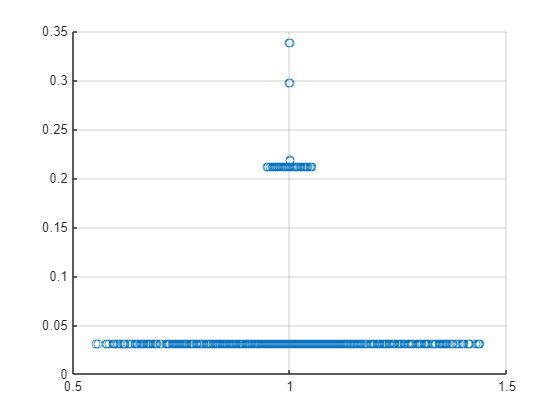



figure();
swarmchart(ones(Nruns, 1), CoupledCost(1, :)' + CoupledCost(2, :)', 'Marker','o');
grid on;